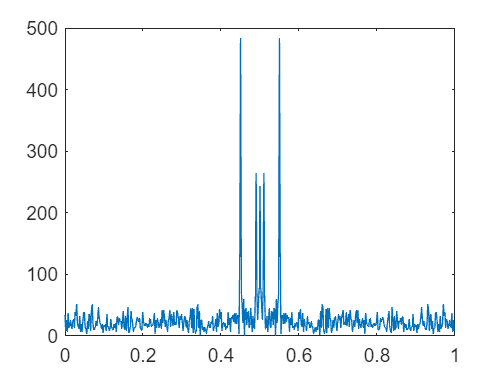

t = randperm(800,502);
S = 2*sin(0.1*pi*t) + sin(0.02*pi*t);
tr = 0:300;
Sr = 2*sin(0.1*pi*tr) + sin(0.02*pi*tr);
X = S + rand(size(t));
Y = fftshift(nufft(X, t));
Yr = fftshift(fft(Sr,length(tr)));
n = length(t);
f = (0:n-1)/n;
plot(f,abs(Y))

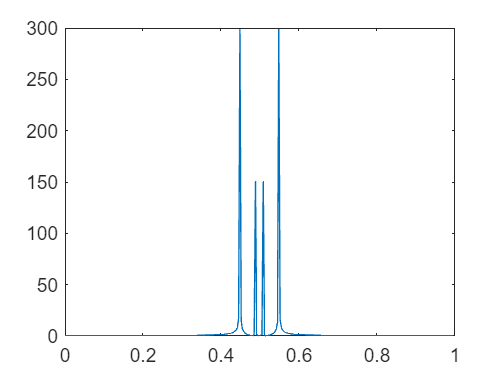

nr = length(tr);
fr = (0:nr-1)/nr;
plot(fr, abs(Yr))